# ** Vision Artificial. GIEC, GITT.**

# **	Sistemas de Vision Artificial. GII, GISI, GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: Clasificadores (Supervised Learning)

**Nota**. Se necesita tener instalada la toolbox `"Statistics and Machine Learning"`

El objetivo de este ejercicio es entrenar clasificadores utilizando la base de datos  `hospital.mat `de Matlab, que contine datos simulados de 100 pacientes. Además se van a calcular las principales métricas para evaluar el funcionamiento de los clasificadores estudiados.

## k-Nearest Neighbour (kNN)

El primer clasificador que se va a estudiar es el k vecinos más próximos ([fitcknn](https://www.mathworks.com/help/stats/fitcknn.html)). Para ello se van a realizar los siguientes pasos:

- Se divide la base de datos `hospital` en dos grupos: 70% para entrenamiento y 30% para test, visualizando los datos usando un gráfico de dispersión.

clear all;
close all;

% --- (1) ---
% Base de datos hospital 
load hospital;

% se utiuliza solo la presión sanguinea
data = [hospital.BloodPressure];
labels = categorical(hospital.Smoker,[1 0],{'Smoker' 'Non-Smoker'});


% 70% para entrenamiento y 30% para test
cv = cvpartition(size(data,1),"HoldOut",0.3);

% datos para entrenamiento
data_train = data(cv.training,:);
label_train = labels(cv.training);
tbl_train = tabulate(label_train)
% plot de los datos de entrenamiento
figure
gscatter(data_train(:,1),data_train(:,2), label_train,'rb','o+',8,'on')
xlabel('Systolic BloodPressure');
ylabel('Diastolic BloodPressure');
legend('Location','northwest');
title(sprintf('Trainig data\n %s %d (%.1f%%)/ %s %d (%.1f%%)'...
     ,tbl_train{1,1}, tbl_train{1,2}, tbl_train{1,3}, tbl_train{2,1}, tbl_train{2,2}, tbl_train{2,3}));
grid on;

% datos para test
data_test = data(cv.test, :);
label_test = labels(cv.test);
tbl_test = tabulate(label_test)

% plot de los datos de test
figure
gscatter(data_test(:,1),data_test(:,2), label_test,'gm','o+',8,'on')
xlabel('Systolic BloodPressure');
ylabel('Diastolic BloodPressure');
legend('Location','northwest');
title(sprintf('Test data\n %s %d (%.1f%%)/ %s %d (%.1f%%)'...
    ,tbl_test{1,1}, tbl_test{1,2}, tbl_test{1,3}, tbl_test{2,1}, tbl_test{2,2}, tbl_test{2,3}));
grid on;

- Se entrena el clasificador kNN cambiando `k` (`K = 1, 5, 10, 15`), visualizando la superficie de decisión. 

% --- (2) ---
fig = figure;

% máximo 4 valores de k
k = [1, 5, 10, 15];
for i = 1:numel(k)

    % Entrenamiento
    Model_kNN{i} = fitcknn(data_train,label_train,'NumNeighbors',k(i));
    classifier_name{i} = sprintf('kNN k=%d', k(i));

    % visualización superficies de decisión 
    subplot(2,2,i);
    plot_decision_surface(fig, Model_kNN{i}, data_train, 0.1, 'cy')
    hold on;
    gscatter(data_train(:,1),data_train(:,2), label_train,'rb','o+',8,'on')
    title(classifier_name{i})
    legend off, 
    axis tight
    hold off;
end
legend({'Smoker' 'Non-Smoker'},'Location',[0.35,0.01,0.35,0.05],'Orientation','Horizontal')

**Se pide:**

- Complete los parámetros de las funciones [predict](https://es.mathworks.com/help/stats/linearmodel.predict.html) y [confusionchart](https://es.mathworks.com/help/stats/confusionchart.html?s_tid=srchtitle_support_results_1_confusionchart) para evaluar los clasificadores kNN con los **datos de test**.

- Complete la función '`scores_binary_cm()`'  para calcular los parámetros: `Recall`, `Precision`, `F1_score`, y  `Accuracy `a partir de la matriz de confusión considerando como clase positiva (`P`) los fumadores (`'Smoker'`). 

% --- (3) ---

% Se obtiene la predicción de los valores de Test
CM = zeros(2,2,numel(k));
kNN_scores = zeros(numel(k),4);
fig = figure;
for i = 1:numel(k)
    
    %% ===> COMPLETAR AQUÍ! los parámetros de la función predict() ===
    predictions_kNN = predict();
    
    %% ===> COMPLETAR AQUÍ! los parámetros de la función confusionchart() ===
    subplot(2,2,i);
    cm = confusionchart();
    title(classifier_name{i})

    %% ===> ir a la función 'scores_binary_cm' y COMPLETAR!
    kNN_scores(i,:) = scores_binary_cm(cm.NormalizedValues);
    
end

T_scores = array2table(kNN_scores,'RowNames', classifier_name,'VariableNames',{'Recall','Precision', 'F1_score','Accuracy'})


**Se pide:**

- Compare varios clasificadores utilizando la **APP** [*Clasification Learner*](https://es.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html#responsive_offcanvas) dentro de *Machine Learning and Deep Learning. *Para abrir Clasificator Learner, en la pestaña **Apps**, en **Machine Learning and Deep Learning**, haga clic en el icono de la app. Como alternativa, puede abrir la app desde la línea de comandos:

`clasificationLearner`

Sigua los siguientes pasos:

- Cargue una nueva sesión y elija seleccionar los datos desde el workspace, tal y como se muestra en la siguiente imagen.

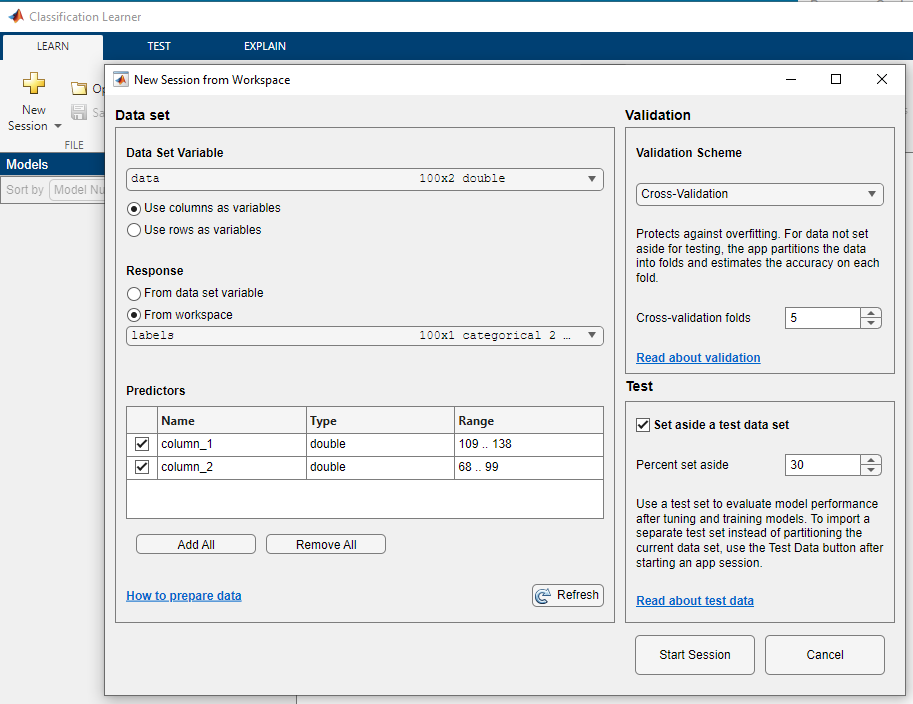

- Seleccione: `Fine KNN` (con k=5), **Gaussian Naive Bayes** y **Linear SVM.** Entrénelos y compare los resultados.

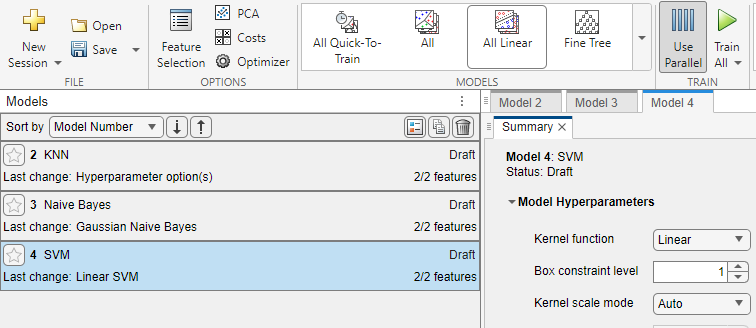

# Funciones

function plot_decision_surface(fig, model, data, resolution, color)
    
    figure(fig)
    
    x1range = min(data(:,1)):resolution:max(data(:,1));
    x2range = min(data(:,2)):resolution:max(data(:,2));
    [xx1, xx2] = meshgrid(x1range,x2range);
    XGrid = [xx1(:) xx2(:)];
    
    predictions = predict(model,XGrid);
    gscatter(xx1(:), xx2(:), predictions, color);

end

function [Scores] = scores_binary_cm(CM)

    if size(CM) == [2,2]
        %% ===> COMPLETAR AQUÍ! las ecuaciones de las métricas Recall, Precision, F1_score y Accuracy
        Recall    = [];
        Precision = [];
        F1_Score  = [];
        Accuracy  = [];
    else
        error('scores_binary_cm:CM', 'la matriz de confusión debe ser 2x2, calisifcador binario.');
    end

    Scores = [Recall' Precision' F1_Score' Accuracy'];
   
end
